# Example 2: Generation of velocity histories

 In the example 2, a higher sampling frequency is used with only 49 nodes. The point is to compare the simulated and target power spectral densities (PSDs)

## Set sampling frequency and record duration

clearvars;close all;clc;

fs = 9; % sampling frequency (in Hertz)
M = 15; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs);

Duration of target time series is 1.01 hours, i.e. 3.64e+03 sec 



N=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)



## Set the geometry (a simple grid)

Nyy = 5; % number of nodes along the y axis
Nzz = 5; % number of nodes along the z axis

ymin = -50;
ymax = 50;

zmin= 1;
zmax = zmin +150;


y = linspace(ymin,ymax,Nyy);
z = linspace(zmin,zmax,Nzz);

[Y,Z] = meshgrid(y,z);

## Visualization of the grid

The dots show where the velocity fluctuations are going to be generated

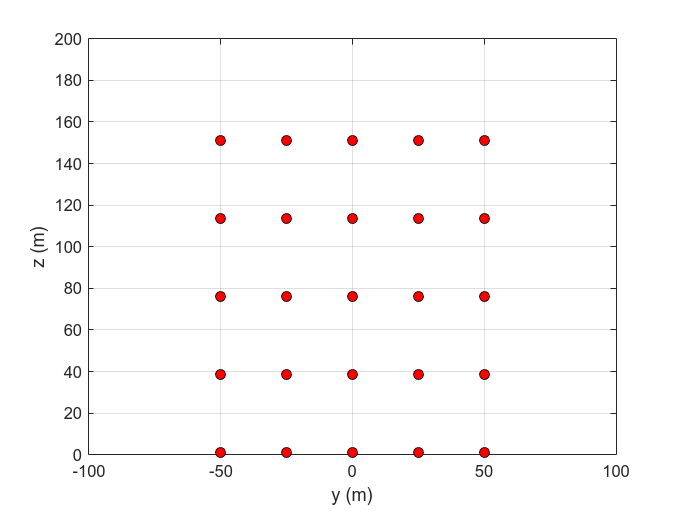

clf;close all
figure
axis equal
plot(Y(:),Z(:),'ko','markerfacecolor','r')
xlabel('y (m)')
ylabel('z (m)')
xlim([-100,100])
ylim([0 200])
grid on

set(gcf,'color','w')

## Set the target mean wind velocity

u_star = 0.8; % Friction velocity (m/s);
kappa = 0.4; % von karman constant
z0 = 0.03; % roughness length;

logProfile = @(u_star,z,z0,kappa)  u_star/kappa.*log(z./z0)

logProfile = function_handle with value:
    @(u_star,z,z0,kappa)u_star/kappa.*log(z./z0)


U = logProfile(u_star,Z,z0,kappa);


## Set the target wind coherence parameters

The davenport model is used for the sake of simplicity

CohDecay.Cuy = 7; % Arbitrary decay coefficient for u in the "y" direction
CohDecay.Cuz = 10; % Arbitrary decay coefficient for u in the "z" direction
CohDecay.Cvy = 7; % Arbitrary decay coefficient for v in the "y" direction
CohDecay.Cvz = 10; % Arbitrary decay coefficient for v in the "z" direction
CohDecay.Cwy = 6.5; % Arbitrary decay coefficient for w in the "y" direction
CohDecay.Cwz = 3; % Arbitrary decay coefficient for w in the "z" direction


## Set the wind spectral density at each nodes

Su, Sv, Sw and Suw are not normalized here! They are expressed as [Nm x N] matrices where Nm = Nz x Ny.

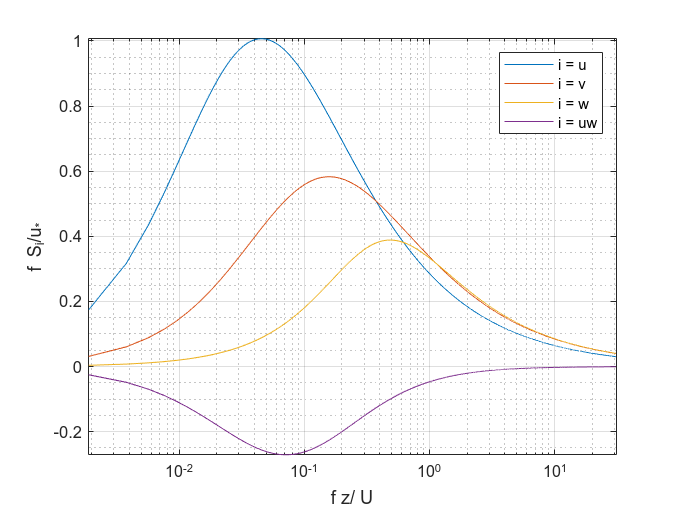

[Su,Sv,Sw,Suw,~] = KaimalModel(U,Z,f,u_star);

[~,indZ]=min(abs(Z(:,1)-100));

coeff = f./u_star.^2;
fr = f.*Z(indZ,1)./U(indZ,1);
figure
semilogx(fr,coeff.*Su(indZ,:),fr,coeff.*Sv(indZ,:),...
    fr,coeff.*Sw(indZ,:),fr,coeff.*Suw(indZ,:))
axis tight
ylabel('f S_i/u_*')
xlabel('f z/ U')
legend('i = u','i = v','i = w','i = uw')
set(gcf,'color','w')
grid on
grid minor

## Run the function windSimFast

The PSDs of the velocity are calculated outside the function windSimFast, whereas the coherence is calculated inside the function windSimFast to keep a balance between robustness and code performance. 


tic
[u,v,w,nodes] = windSimFast(U,f,Su,Sv,Sw,CohDecay,Y,Z,'Suw',Suw); %  Suw is here an option!

Expected computation time: From 6 to 14 seconds 


toc

Elapsed time is 4.844184 seconds.



u = bsxfun(@plus,u,U(:)');
u = reshape(u,N,Nzz,Nyy); % whos u1
v = reshape(v,N,Nzz,Nyy); % whos u1
w = reshape(w,N,Nzz,Nyy);% whos w1

fprintf('Mean wind speed for w is %1.2f m/s \n',mean(w(:),'omitnan')); % check is zero m/s

Mean wind speed for w is -0.00 m/s 


fprintf('Mean wind speed for v is %1.2f m/s \n',mean(v(:),'omitnan')); % check is zero m/s

Mean wind speed for v is 0.00 m/s 


## Time series overview


[~, indEnd] = min(abs(t-150))

indEnd = 1351

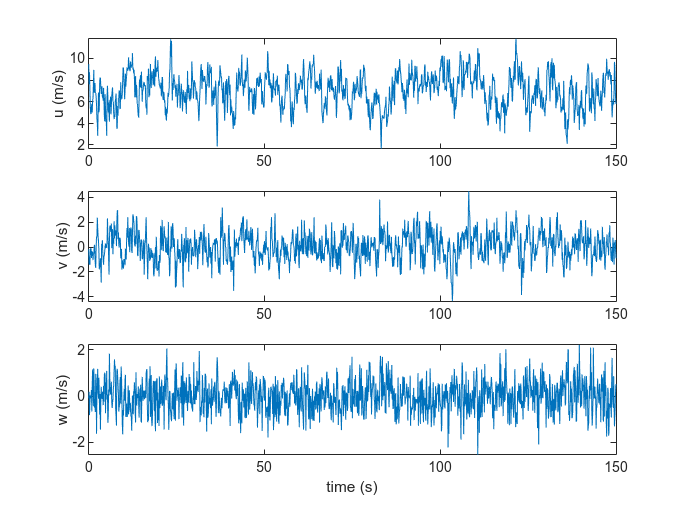


clf;close all;
figure
subplot(311)
plot(t(1:indEnd),squeeze(u(1:indEnd,1,1)))
ylabel('u (m/s)')
axis tight
subplot(312)
plot(t(1:indEnd),squeeze(v(1:indEnd,1,1)))

ylabel('v (m/s)')
axis tight
subplot(313)
plot(t(1:indEnd),squeeze(w(1:indEnd,1,1)))
xlabel('time (s)')
ylabel('w (m/s)')
axis tight

set(gcf,'color','w')

## Mean profile of the wind speed

THis is simply done to check that the matrix u, v and w have been properly reshaped from 2D to 3D matrices

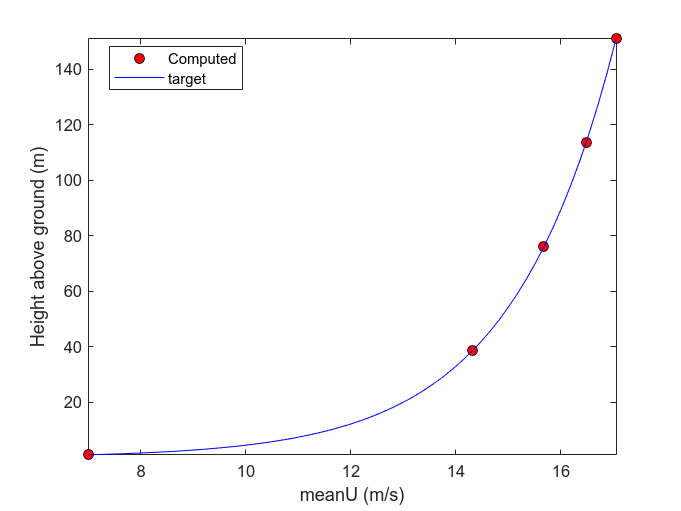

clf;close all;
figure

plot(squeeze(mean(u(:,:,1))),z,'ko','markerfacecolor','r')
hold on
z1 = logspace(log10(z(1)),log10(z(end)),60);
plot(logProfile(u_star,z1,z0,kappa),z1,'b')
legend('Computed','target','location','best')
xlabel('meanU (m/s)')
ylabel('Height above ground (m)')
axis tight

set(gcf,'color','w')

## PSD estimates and comparison with target spectrum (kaimal model)

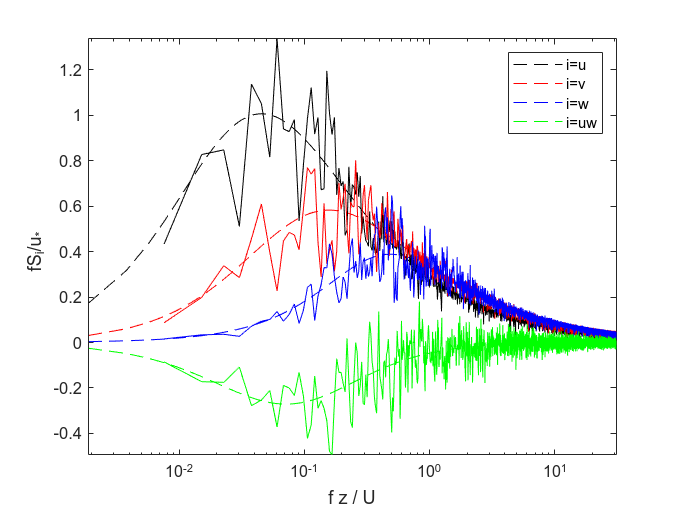


[~,indZ]=min(abs(Z(:,1)-100));
Nf = round(N/4); % numbe of points for each segments (50% overlapping)
[Su0,f0]=pmtm(detrend(squeeze(u(:,indZ,1))),4,Nf,fs);
[Sv0,~]=pmtm(squeeze(v(:,indZ,1)),4,Nf,fs);
[Sw0,~]=pmtm(squeeze(w(:,indZ,1)),4,Nf,fs);
[Suw0,~]=cpsd(detrend(squeeze(u(:,indZ,1))),detrend(w(:,indZ,1)),Nf,round(Nf/2),Nf,fs);

Su0 = f0.*Su0./u_star.^2;
Sv0 = f0.*Sv0./u_star.^2;
Sw0 = f0.*Sw0./u_star.^2;
Suw0 = f0.*real(Suw0)./u_star.^2;

fr0 = Z(indZ,1)./U(indZ,1).*f0;

fr = Z(indZ,1)./U(indZ,1).*f;


coeff = f./u_star.^2;
clf;close all;
figure
semilogx(fr,coeff.*Su(indZ,:),'k--',fr,coeff.*Sv(indZ,:),...
    'r--',fr,coeff.*Sw(indZ,:),'b--',fr,coeff.*Suw(indZ,:),'g--')
hold on; box on;
semilogx(fr0,Su0,'k',fr0,Sv0,'r',fr0,Sw0,'b',fr0,Suw0,'g')
% hold on
% plot([1 10],0.3*[1 10].^(-2/3),'m')
xlabel('f z / U')
ylabel('fS_i/u_* ')
axis tight
set(gcf,'color','w')
legend('i=u','i=v','i=w','i=uw')

## Co-Coherence estimation (vertical separations)

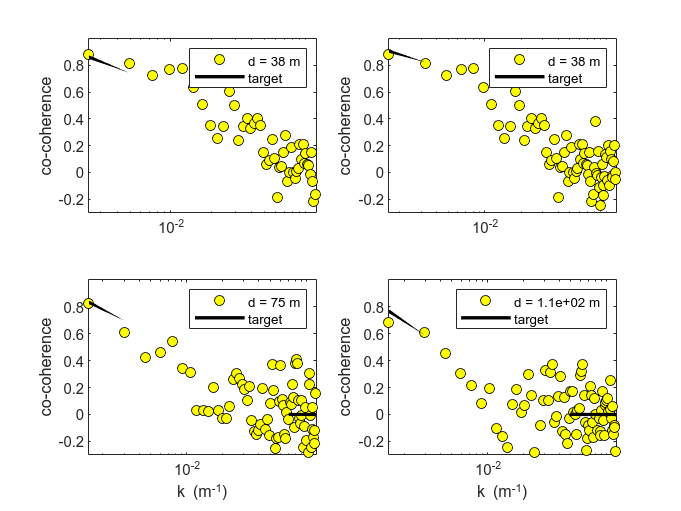

Nblock = 10; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);
if mod(Ncoh,2)
    cocoh = zeros(Nzz,Nzz,round(Ncoh/2));
else
    cocoh = zeros(Nzz,Nzz,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function coherence
for ii=1:Nzz
    for jj=1:Nzz
        [cocoh(ii,jj,:),~,freq] = coherence(u(:,jj,1),u(:,ii,1),Ncoh,round(Ncoh/2),Ncoh,fs);
    end
end
% matrix distance along y
dz = abs(z(:)-z(:)');
uCoh = 0.5* abs(U(:,1)+U(:,1)'); % average between two heights


distTarget = [25,50,75,100];
figure
for ii=1:numel(distTarget)
    [~,indDist] = min(abs(dz(1,:)-distTarget(ii)));
    k = 2*pi*freq./uCoh(1,ii);
    subplot(2,2,ii)
    semilogx(k,squeeze(cocoh(1,indDist,:)),'ko','markerfacecolor','y');
    box on;hold on
    plot(k,exp(-CohDecay.Cuz.*dz(1,indDist).*freq/uCoh(1,ii)),'k','linewidth',2);
    legend(['d = ',num2str(dz(1,indDist),2),' m'],'target');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
end

## Write data into a bts file



zHub = 150;
ntower = 0;
fname = 'testFile.bts';
U = mean(mean(u,'omitnan'),3,'omitnan');
z1 = nodes.Z(:,1);
z = nodes.Z(:,1);
y = nodes.Y(1,:)';
if z(1)>z(end),

    z = flipud(z);
    u = flip(u,2);
    v = flip(v,2);
    w = flip(w,2);
end
uHub = interp1(z1,U(:),zHub,'cubic');
write2bts(fname,u,v,w,t,y,z,zHub,uHub,ntower);

Reading from the file testFile.bts with heading: 
   "This full-field file was generated by windSimFast".


fprintf([fname,' is saved \n'])

testFile.bts is saved 



% check bts file
% [velocity, twrVelocity, y, z, zTwr, nz, ny, dz, dy, dt, zHub, z1, Vslope, Voffset] = readTSgrid(fname);
% 
% N = size(velocity,1);
% t = [0:1:N-1]*dt;
% [Y,Z] = meshgrid(y,z);
% u = reshape(squeeze(velocity(:,1,:,:)),N,[]);
% v = reshape(squeeze(velocity(:,1,:,:)),N,[]);
% w = reshape(squeeze(velocity(:,1,:,:)),N,[]);
% 
% figure
% plot(mean(u,'omitnan'),reshape(Z',[],1),'o')

